# Determine Is from fit of the V(I)

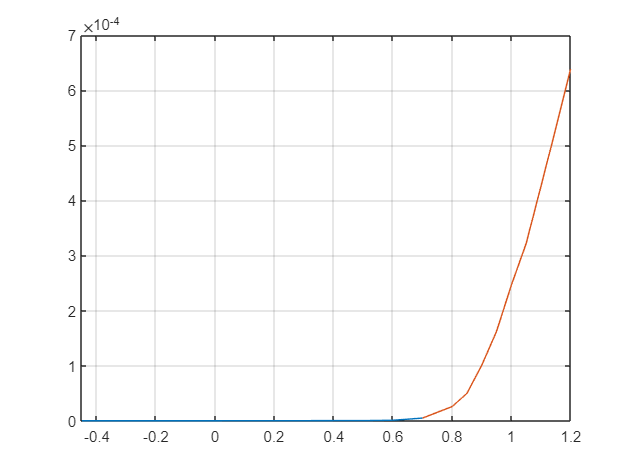

clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';
dummyStr = strsplit(LPath, '.');
SPath = [dummyStr{1}, '.mat'];
clear dummyStr

conv = 20e3; %Ohm

if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/conv;   
end
Iraw = Iraw + abs(Iraw(Vraw == 0));
start = 5;
V = Vraw(start:end);
I = abs(Iraw(start:end));

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

TEMPERATURE = 300;
THERMAL_VOLTAGE = 0.02585;
Rs0 = 400;
alpha0 = 15;
% Is0 = 1e-12;
Is0 = 4;
p0 = [Rs0, alpha0, Is0]

p0 =    400    20     4


% T0 = 300/(alpha0*0.02585*2);
n0 = 1/(alpha0*THERMAL_VOLTAGE)

n0 = 1.9342

T = 300/(alpha0*THERMAL_VOLTAGE*n0)

T = 300

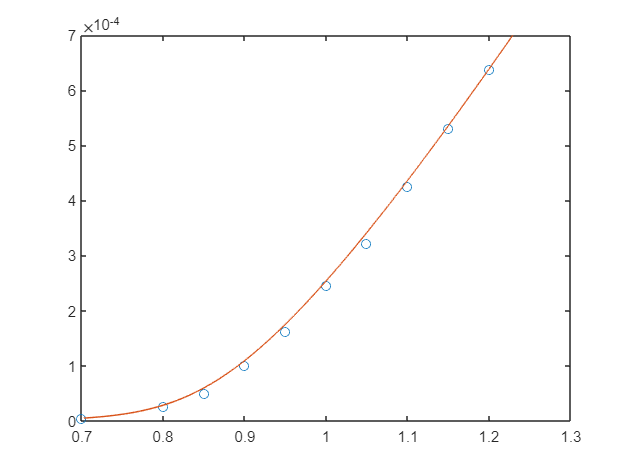

% C(1) = Rs, C(2) = 1/alpha, C(3) = 1/Is
Vmodel = @(I, C) C(1)*I + 1/C(2)*log(I/(C(3)*1e-12) + 1);

II = linspace(Iraw(start), 7e-4, 10000);
figure()
plot(V, I, 'o')
hold on
plot(Vmodel(II, p0), II)

Fit = esfit(V, @(p) Vmodel(I, p), p0, p0);

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)Vmodel(I,p)
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 4.72281e-03   edge 1.00000e-01   initial simplex
iteration   2: value 4.72281e-03   edge 8.00000e+01   reflection
iteration   3: value 4.72281e-03   edge 5.33333e+01   contraction outside
iteration   4: value 4.72281e-03   edge 5.33333e+01   contraction inside
iteration   5: value 4.22723e-03   edge 4.63975e+01   contraction inside
iteration   6: value 4.19445e-03   edge 4.69431e+01   contraction inside
iteration   7: value 4.19445e-03   edge 5.08395e+01   reflection
iteration   8: value 3.70033e-03   edge 2.76846e+01   reflection
iteration   9: value 3.70033e-03   edge 2.76846e+01

% esfit(V, @(p) Vmodel(I, p), p0, p0);
Fit.pfit

ans =   393.2064
   18.1440
    8.0000


Rs = Fit.pfit(1); alpha = Fit.pfit(2); Is = 1e-12*Fit.pfit(3);
dRs = Fit.pstd(1); dalpha = Fit.pstd(2); dIs = Fit.pstd(3);
n = 1/(alpha*0.02585); dn = 10;
mssg = [
    sprintf('Rs = %f +- %f\n', Rs, dRs), ...
    sprintf('alpha = %f +- %f, n = %f +- %f\n', alpha, dalpha, n, dn), ...
    sprintf('Is = %e +- %e\n', Is, dIs)
    ];
disp(mssg)

Rs = 393.206405 +- 0.051843
alpha = 18.144002 +- 1.123520, n = 2.132094 +- 10.000000
Is = 8.000000e-12 +- 4.611410e+00



T = 300/(alpha*THERMAL_VOLTAGE*n)

T = 300

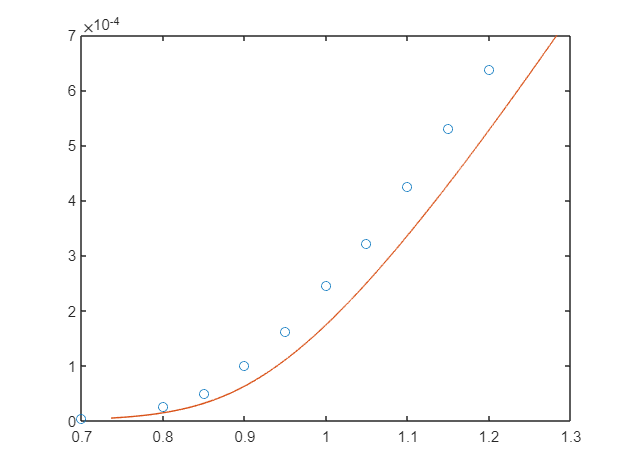

figure()
plot(V, I, 'o')
hold on
plot(Vmodel(II, Fit.pfit), II)

## Divide logarithmic and linear part of the fit

TEMPERATURE = 300;
THERMAL_VOLTAGE = 0.02585;

NUM_Is = 100;
Iss = linspace(0.1, 10, NUM_Is);
NUM_ALPHA = 100;
alphaMax = 1/(1.3*THERMAL_VOLTAGE);
alphaMin = 1/(1.9*THERMAL_VOLTAGE);
alphas = linspace(alphaMin, alphaMax, NUM_ALPHA);
Rs0 = 400;

Vmodel = @(I, C) C(1)*I + 1/C(2)*log(I/(C(3)*1e-12) + 1);
p0 = [Rs0, alphas(1), Iss(1)];

Invalid expression. When calling a function or indexing a variable,
use parentheses. Otherwise, check for mismatched delimiters.

p0 = repmat({p0}, NUM_Is, NUM_ALPHA);

Vary = [200, 5, 10];
Fit = esfit(V, @(p) Vmodel(I, p), p0, Vary);
Fit = repmat({Fit}, nIs, 1);
parfor iIs = 1:nIs
    % Is0 = 1e-12;
    Is0 = Iss(iIs);
    Fit{iIs} = esfit(V, @(p) Vmodel(I, p), [Rs0, alpha0, Is0], Vary);
end